clear;
clc;close all;

addpath('./flann/');

s=10;
gridStep=0.3;
scale_detect_gridstep=1;
max_scale_detect_size=150;
overlap=0.5;
icpSteps=200;
TrMin=0.3;
TrMax=0.9;
%尺度平衡子（让待配准的两幅图比例保持又不过多影响gridstep）
zoomVar=1;
downStep=0.03;

## 转灰度

map1=rgb2gray(imread('D:\workspaceMatlab\grid_map_regis_project\map_data\map_different_scale\Fr79a1_5.png'));
map2=rgb2gray(imread('D:\workspaceMatlab\grid_map_regis_project\map_data\map_different_scale\Fr79a2_10.png'));
% map1=rgb2gray(imread('D:\workspaceMatlab\grid_map_regis_project\map_data\pair2\2_25.png'));
% map2=rgb2gray(imread('D:\workspaceMatlab\grid_map_regis_project\map_data\pair2\4_25.png'));
% map1 = rgb2gray(imread('../map_data/pair3/1.jpg'));
% map2 = rgb2gray(imread('../map_data/pair3/2.jpg'));
% imshowpair(map1,map2);
tic;


harris点 

% figure
% imshow(map1);hold on
corner_Point1 = detectHarrisFeatures(map1);
sele_corner_points1 =corner_Point1.selectUniform(300,size(map1));
% plot(sele_corner_points1);
% showPoint(corner_Point1.Location);
%% 灰度角点
% % figure
% % imshow(map1);hold on
% % gray1 = edge(map1);
% % corner_Point2 = detectHarrisFeatures(gray1);
% % plot(corner_Point2.selectUniform(300,size(map1)));
% cornersM1=SURFPoints(result(1:2,sele)','Scale',result(3,sele));

% figure
% imshow(map2);hold on
corner_Point2 = detectHarrisFeatures(map2);
sele_corner_points2 =corner_Point2.selectUniform(300,size(map2));
% showPoint(corner_Point2.Location);


#### 提取二维点云

[~,pointCMap1]=exarctPCfroImg(map1);
% figure
% showPoint(pointCMap1,true)
% axis equal
% axis off
% figure
[~,pointCMap2]=exarctPCfroImg(map2);
% showPoint(pointCMap2,true)
% axis equal
% axis off

#### 尺度检测

% 2.均匀分布选取harris角点最强点200个    (current) 
% figure;
% imshow(map1);hold on;
points_scale1 = detectScale(pointCMap1,sele_corner_points1.Location,scale_detect_gridstep,max_scale_detect_size);
% draw_circle(points_scale1.Location(1:300,:),points_scale1.ScaleRadius(1:300,:));
% showPoint(points_scale1.Location(1:300,:),true)
% 
% figure;
% imshow(map2);hold on;
points_scale2 = detectScale(pointCMap2,sele_corner_points2.Location,scale_detect_gridstep,max_scale_detect_size);
% draw_circle(points_scale2.Location(1:300,:),points_scale2.ScaleRadius(1:300,:));
% showPoint(points_scale2.Location(1:300,:),true)

% 

存储尺度点（加缩放）

zSeleCorM1=HarrisGridPoints(points_scale1.Location/s,points_scale1.ScaleRadius/s);
zSeleCorM2=HarrisGridPoints(points_scale2.Location/s,points_scale2.ScaleRadius/s);


### 点云整体缩放s

pointCMap1=pointCMap1/s;
pointCMap2=pointCMap2/s;


### 基于尺度获取描述子

[M1Desp,M1Scale,M1Seed,M1Norm]=exarctEIG2d(pointCMap1,gridStep,zSeleCorM1,zoomVar); 
[M2Desp,M2Scale,M2Seed,M2Norm]=exarctEIG2d(pointCMap2,gridStep,zSeleCorM2,zoomVar); 


## 匹配

[Motion,match_1Seed2d,match_2Seed2d,match_oriSeedNum,match_srcSeedsetori,match_tarSeedsetori]=eigMatch2D(M1Desp,M2Desp,M1Scale,M2Scale,M1Seed,M2Seed,M1Norm,M2Norm,overlap,gridStep,map1,map2,s);

% [Motion,match_1Seed2d,match_2Seed2d]=eigMatch2D_noPropogation(M1Desp,M2Desp,M1Scale,M2Scale,M1Seed,M2Seed,M1Norm,M2Norm,overlap,gridStep,map1,map2,s);

## 修正尺度 

s=SQRT((S*COS(THETA))^2+(S*SIN(THETA))^2)

%%根据相似变换和比例公式推倒缩放因子 ori_scaleC
ori_scaleC=sqrt(sum(Motion(1:2,1).^2));

## display match

% show_protan(map1,map2,match_1Seed2d,match_2Seed2d,s);
% show_protan(map1,map2,match_1Seed2d,match_2Seed2d,s,match_srcSeedsetori,match_tarSeedsetori);
% show_protangonation_claw(map1,map2,match_1Seed2d,match_2Seed2d,s);
% show_protangonation_claw_y(map1,map2,match_1Seed2d,match_2Seed2d,s);

scaleC = ori_scaleC;

% map1 = imresize(map1,ori_scaleC);
% corner_Point1 = detectHarrisFeatures(map1);
% sele_corner_points1 =corner_Point1.selectUniform(300,size(map1));
% [pcMap3d1,pointCMap1]=exarctPCfroImg(map1);
% points_scale1 = detectScale(pointCMap1,sele_corner_points1.Location,scale_detect_gridstep,max_scale_detect_size);
% zSeleCorM1=HarrisGridPoints(points_scale1.Location/s,points_scale1.ScaleRadius/s);
% pointCMap1=pointCMap1/s;
% [M1Desp,M1Scale,M1Seed,M1Norm]=exarctEIG2d(pointCMap1,gridStep,zSeleCorM1,zoomVar); 
% [Motion,match_srcSeed3d,match_tarSeed3d]=eigMatch2D(M1Desp,M2Desp,M1Scale,M2Scale,M1Seed,M2Seed,M1Norm,M2Norm,overlap,gridStep,map1,map2,s);
% scaleC=sqrt(sum(Motion(1:2,1).^2));

ICP

pointCMap1Scaled = pointCMap1*scaleC;
pointCMap1Down = pcdownsample2d(pointCMap1,downStep);
pointCMap2ScaledDown = pcdownsample2d(pointCMap2,downStep);
% pointCMap1ScaledDown = pcdownsample2d(pointCMap1,downStep);
% pointCMap2ScaledDown = pcdownsample2d(pointCMap2,downStep);
R0=Motion(1:2,1:2);
t0=Motion(1:2,3);
% opMotion=Motion;
R0=R0./scaleC;%成为刚体变换以ICP
%sicp
[scale_refined, R, t, TriKSIB, minPhi] = FastTrICP(pointCMap2ScaledDown',pointCMap1Down',scaleC,R0,t0,icpSteps,TrMin,TrMax);


fprintf("final scale\t : %f\n",  scale_refined)

final scale	 : 0.500149


fprintf("minPhi\t\t : %f\n", minPhi)

minPhi		 : 0.010878


opMotion=[R.*scale_refined,t;0 0 1];
toc

历时 69.066153 秒。


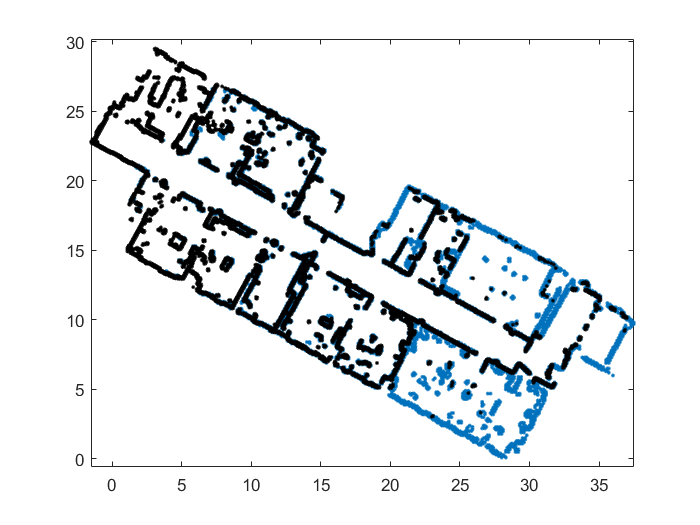

figure;
obtain2d(pointCMap2ScaledDown,'.');hold on;
transMap=opMotion*[pointCMap1Down';ones(1,length(pointCMap1Down))];
obtain2d(transMap,'.k');

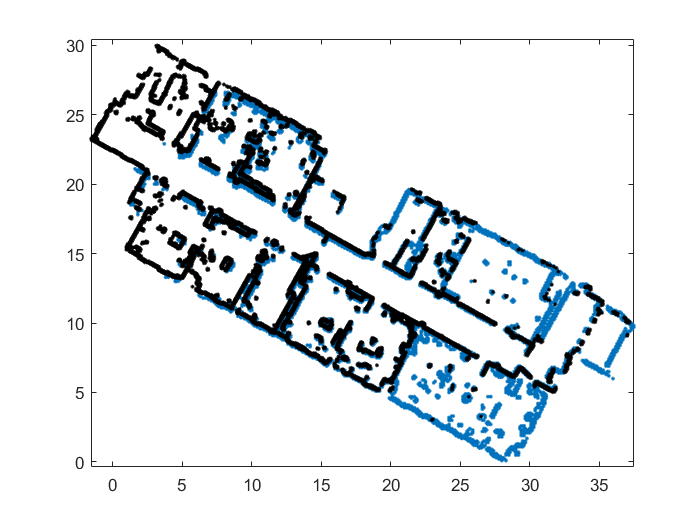


figure;
obtain2d(pointCMap2ScaledDown,'.');hold on;
transMap=[[R0.*scaleC,t0];[0,0,1]]*[pointCMap1Down';ones(1,length(pointCMap1Down))];
obtain2d(transMap,'.k');


% obtain2d(zSeleCorM2.Location,'+r');
% transFeaPoint=opMotion*[zSeleCorM1.Location';ones(1,length(zSeleCorM1.Location))];
% obtain2d(transFeaPoint,'xm');
% pcshow(pcMap3d2);hold on;
% pcshow(pctransform(pcMap3d1,affine3d(Motion')));
% imshow(imrotate(map1,74.0));
% imshowpair(map1,map2);
% imshow(imresize(map1,[200,200]));

#### %%merge_map_image

% get original transform_matrix
% im_motion=[R.*(scale_refined*scaleC),t*s;0 0 1];
% figure
% scale_merge_map(map1,map2,im_motion);


% R0 image
% im_motion=[R0.*(scale_refined*scaleC),t0*s;0 0 1];
% figure
% scale_merge_map(map1,map2,im_motion);